clear
mu_h=67;sig_h=2;
mu_w=150;sig_w=4;
rho=0.75;
S=[sig_h rho*sig_h*sig_w;
   rho*sig_h*sig_w sig_w];

A=chol(S)';
[V,D]=eig(S);
E = V*sqrt(D);

num=10000;

U1A=rand(num,1);
U2A=rand(num,1);

Z1A=sqrt(-2.*log(U1A)).*cos(2*pi.*U2A);
Z2A=sqrt(-2.*log(U1A)).*sin(2*pi.*U2A);

X1A = A(1,1)*Z1A+mu_h;
X2A = A(2,1)*Z1A+A(2,2)*Z2A+mu_w;

mean_height_chol = mean(X1A)

mean_height_chol = 66.9971

mean_weight_chol = mean(X2A)

mean_weight_chol = 150.0062

var_height_chol = var(X1A)

var_height_chol = 2.0077

var_weight_chol = var(X2A)

var_weight_chol = 4.1000

covariance_chol = cov(X1A,X2A)

covariance_chol =     2.0077    0.7466
    0.7466    4.1000


corr_chol = corrcoef(X1A,X2A)

corr_chol =     1.0000    0.2602
    0.2602    1.0000


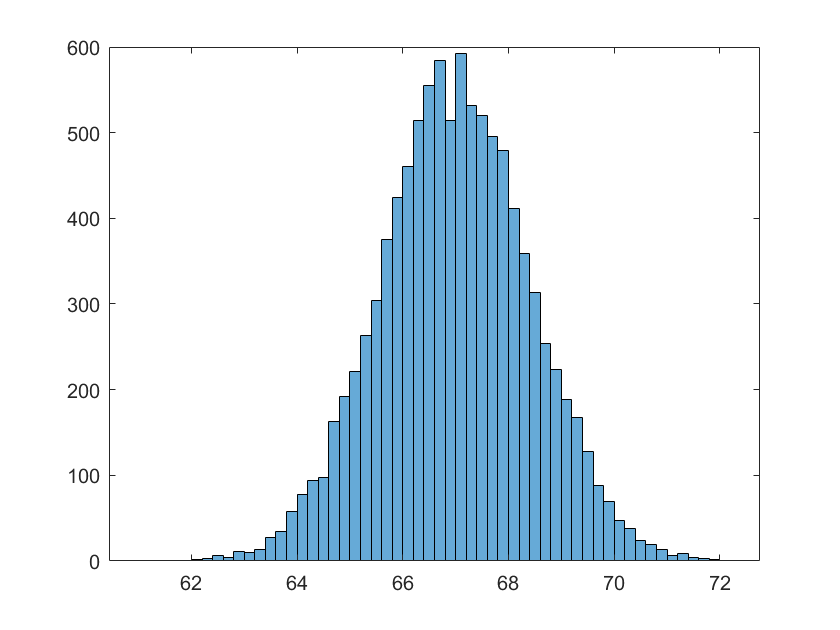

histogram(X1A)

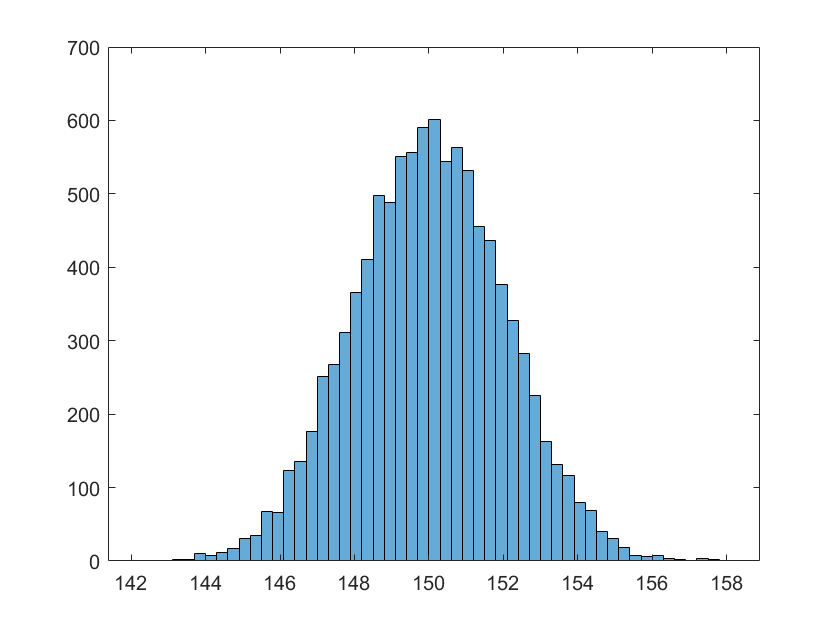

histogram(X2A)

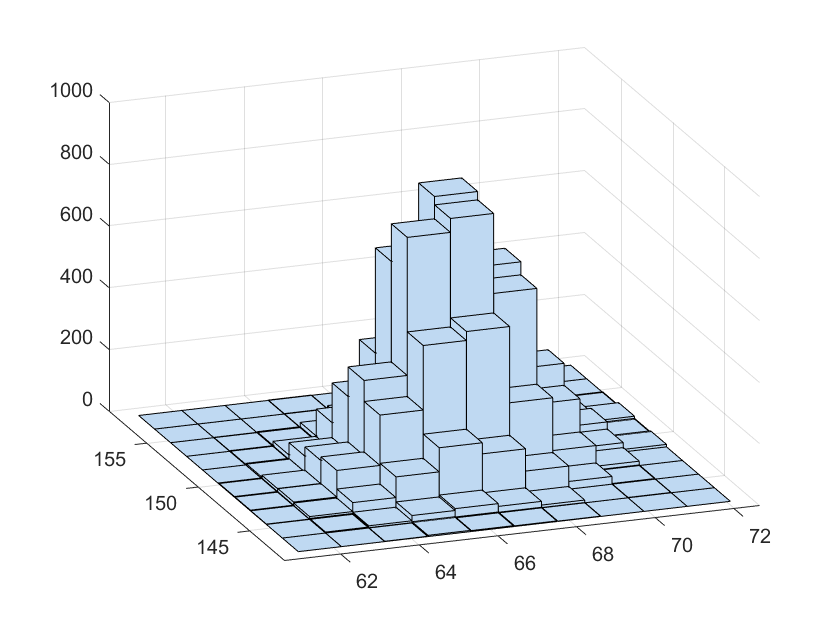

hist3([X1A X2A])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
U1E=rand(num,1);
U2E=rand(num,1);

Z1E=sqrt(-2.*log(U1E)).*cos(2*pi.*U2E);
Z2E=sqrt(-2.*log(U1E)).*sin(2*pi.*U2E);

X1E = E(1,1)*Z1E+E(1,2)*Z2E+mu_h;
X2E = E(2,1)*Z1E+E(2,2)*Z2E+mu_w;

mean_height_eig = mean(X1E)

mean_height_eig = 66.9877

mean_weight_eig = mean(X2E)

mean_weight_eig = 149.9933

var_height_eig = var(X1E)

var_height_eig = 2.0520

var_weight_eig = var(X2E)

var_weight_eig = 4.0144

covariance_eig = cov(X1E,X2E)

covariance_eig =     2.0520    0.7046
    0.7046    4.0144


corr_eig = corrcoef(X1E,X2E)

corr_eig =     1.0000    0.2455
    0.2455    1.0000


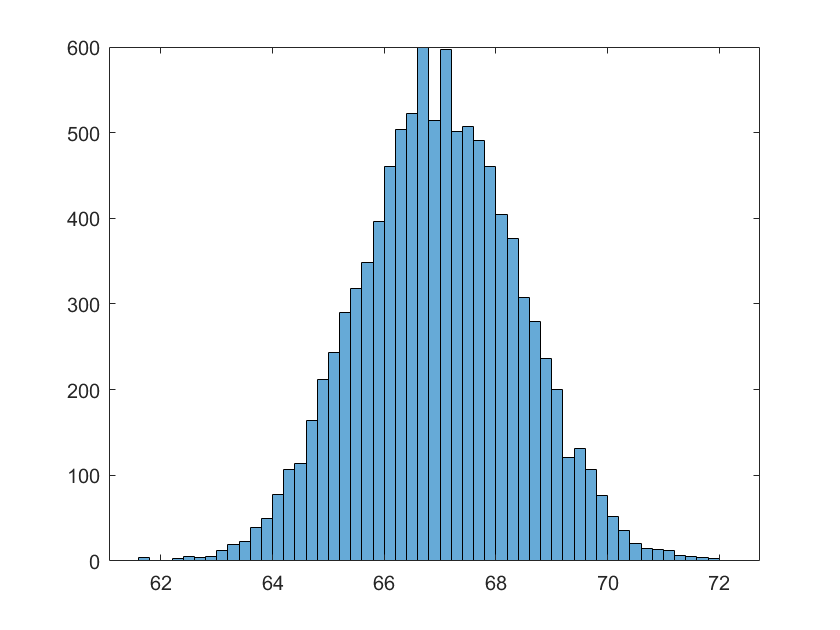

histogram(X1E)

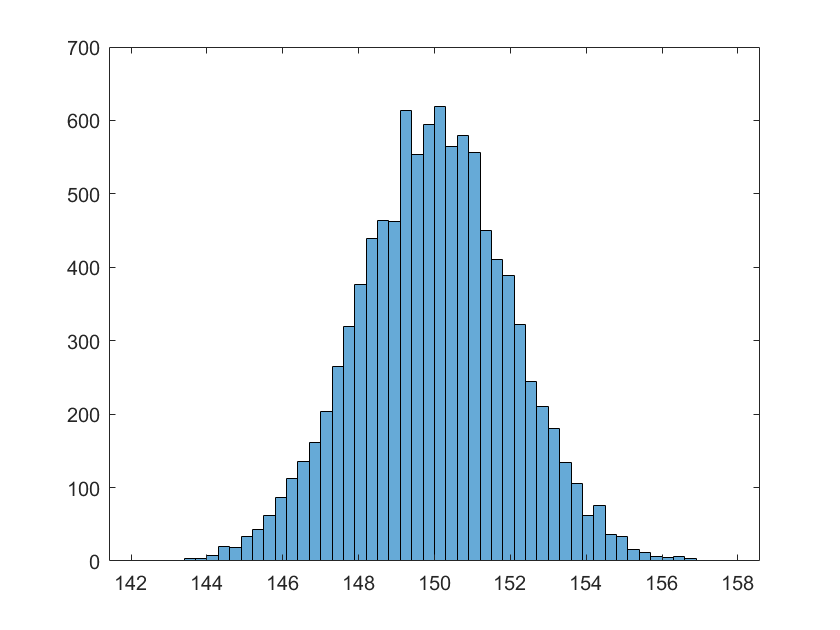

histogram(X2E)

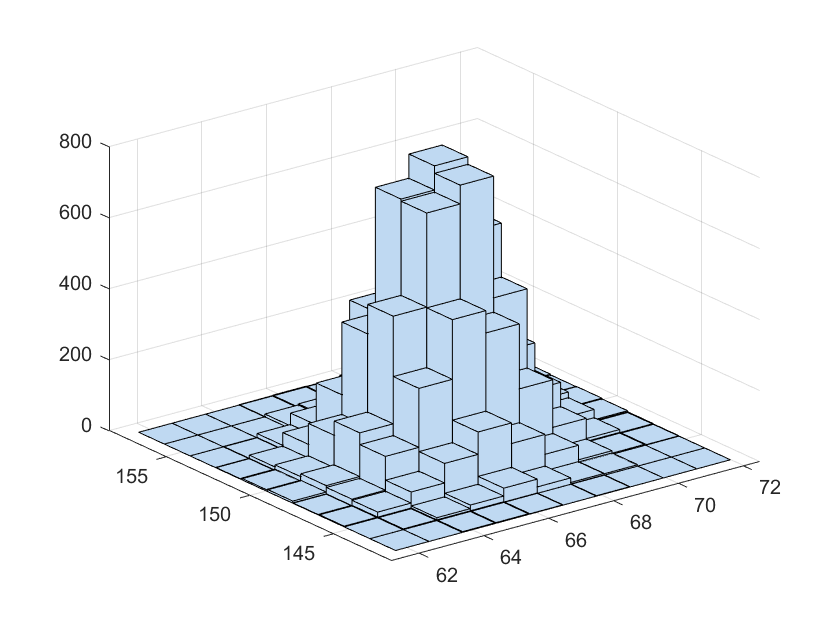

hist3([X1E X2E])